# Example for using the `interpshape` function.

Copyright © 2021 Tamas Kis

Define the points forming the shape.

x = [0,1,2,-3,-5,-2,0];
y = [1,2,5,6,4,-2,1];

Plot the original points together with the shape that they form .

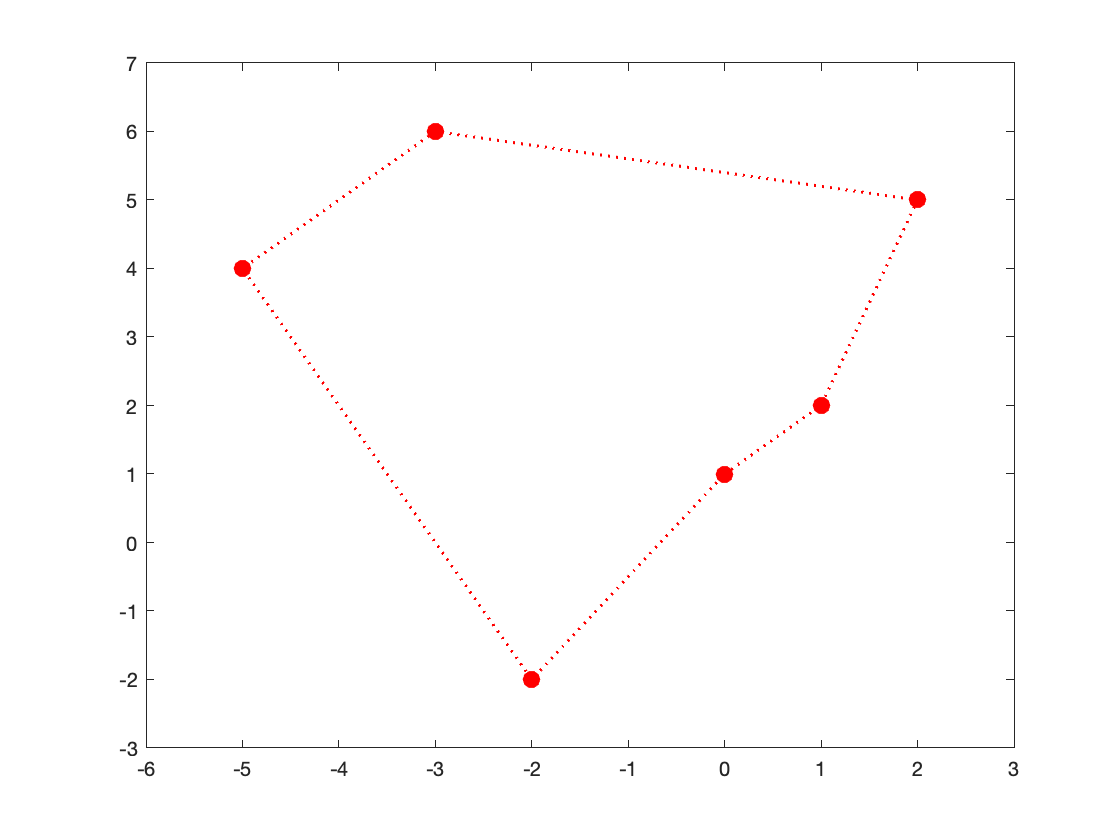

figure;
plot(x,y,'r:.','markersize',30,'linewidth',1.5);
xlim([-6,3]);
ylim([-3,7]);

Expand the number of points by interpolating 5 new points along *each* line connecting the current points.

[x_new,y_new] = interpshape(x,y,5);

Plot the new set of points (note that this new set includes both the new points *and* the old points).

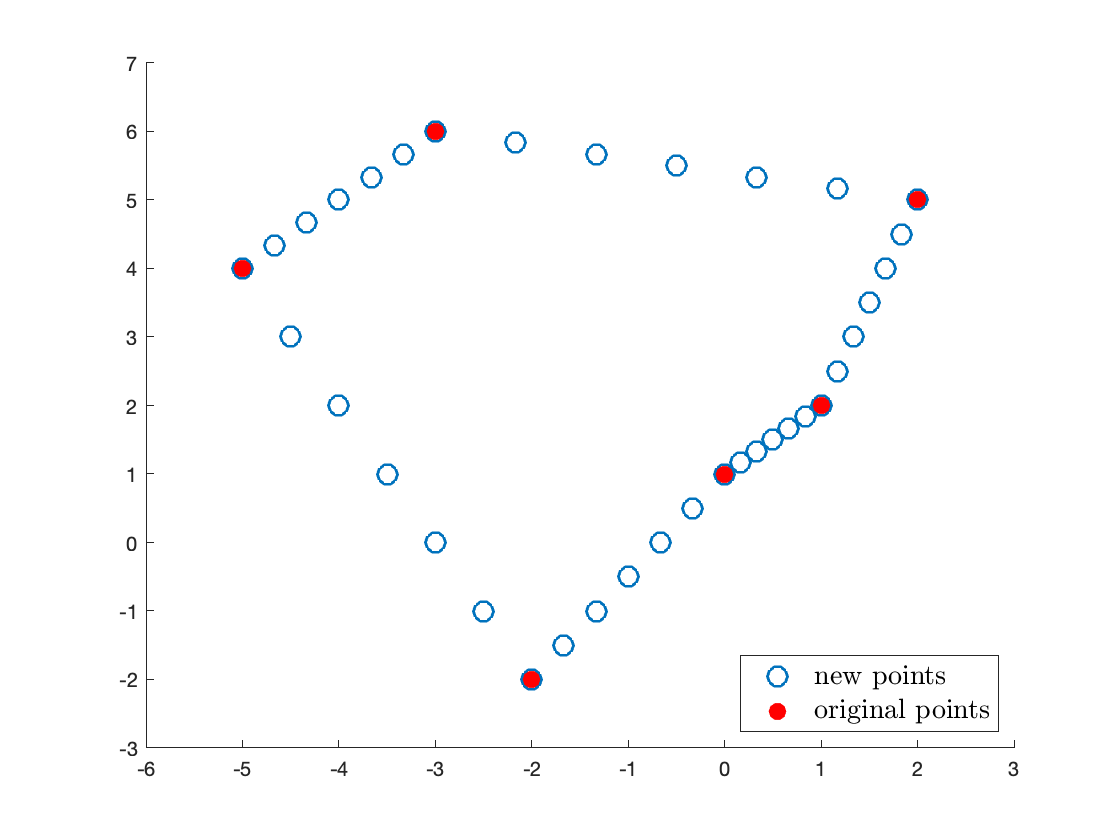

figure;
hold on;
plot(x_new,y_new,'o','markersize',10,'linewidth',1.5);
plot(x,y,'r.','markersize',30,'linewidth',1.5);
hold off;
xlim([-6,3]);
ylim([-3,7]);
legend('new points','original points','interpreter','latex','fontsize',...
    14,'location','southeast');

Draw dotted lines between each point to confirm that the function placed the interpolated points at the correct indices.

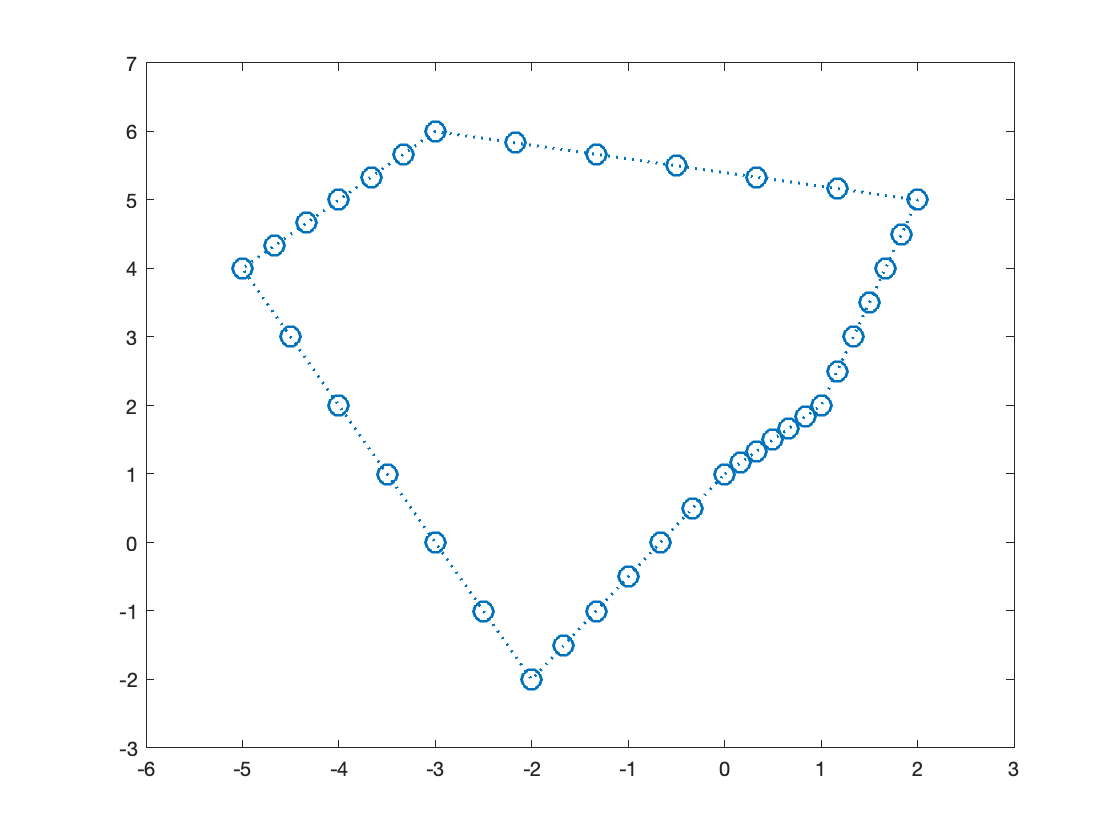

figure;
plot(x_new,y_new,'o:','markersize',10,'linewidth',1.5);
xlim([-6,3]);
ylim([-3,7]);